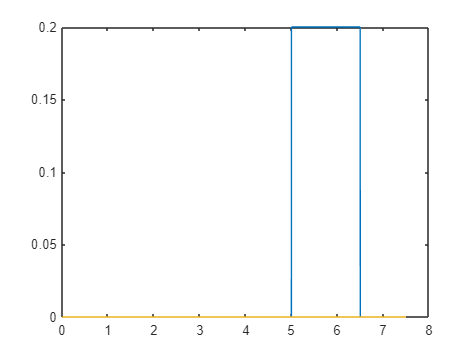


SAMPLE_FREQ = 500;
TIME_END = 6.5;
TIME_JUMP = 5;
VALUE_JUMP = 0.2;
AXIS = 1;

tSample = 1 / SAMPLE_FREQ;

timeVec_1 = (tSample:tSample:TIME_JUMP)';
timeVec_2 = (TIME_JUMP+tSample:tSample:TIME_END)';
timeVec_3 = (TIME_END+tSample:tSample:TIME_END+1)';

traj_1 = 0 .* timeVec_1;
traj_2 = VALUE_JUMP + 0.* timeVec_2;
traj_3 = 0 .* timeVec_3;

timeVec = [timeVec_1; timeVec_2; timeVec_3];
traj_tot = [traj_1; traj_2; traj_3];

traj = struct;
traj.timeVec = timeVec;
traj.theta = [ ...
    traj_tot, ...
    zeros(length(traj_tot),2) ...
    ];

save('traj_stepResponse.mat','-struct','traj')

plot(traj.timeVec,traj.theta)